워크스페이스 정리

clc; clear
cd /home/bong/Project/snake_RL/GD_tor/learning/ray239-ppo/data/

파일 읽어오기

load PPO_OldAPI_512_9_8Dir_403_rl-video4.mat

다음 사용 중 오류가 발생함: load
파일 또는 디렉터리 'PPO_OldAPI_512_9_8Dir_403_rl-video4.mat'을(를) 찾을 수 없습니다.

보상 관련 값 플롯하기

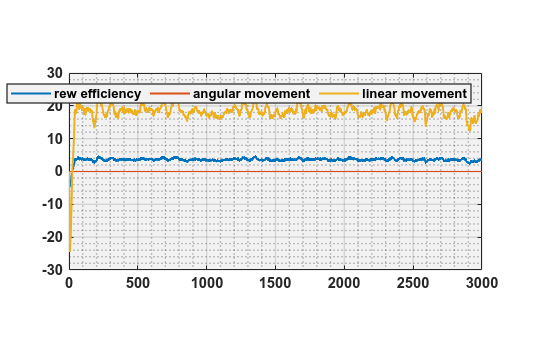

x = length(cost_ctrl);
x = 1:1:x;

h=figure('Units', 'centimeters', 'Position', [5, 5, 15, 10]);
ax = gca; %let user change axis setting
ax.FontSize = 11; %axis fontsize 
ax.LineWidth = 1.0; ax.FontWeight="bold"; %axis linewidth and Fontweight
% ax.GridLineStyle = '--';
% ax.GridLineWidth = 1;
ax.GridColor='#202020';
% fontname(gcf,"Arial") 
ax.Color=[0.95 0.95 0.95];
box
pbaspect([2.1 1 1])

hold on;
%% 그래프 그리기
plot(x, reward_efficiency, 'LineWidth', 1.5, 'LineStyle', '-');
plot(x, reward_angular_movement, 'LineWidth', 1.5, 'LineStyle', '-');
plot(x, rew_linear_movement, 'LineWidth', 1.5, 'LineStyle', '-');

hold off;

legend('rew efficiency', 'angular movement', 'linear movement', Location='northeast',NumColumns=3);

grid on;
box on;
grid minor;

비용 관련 값 플롯하기

x = length(cost_ctrl)

x = 3000

x = 1:1:x

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


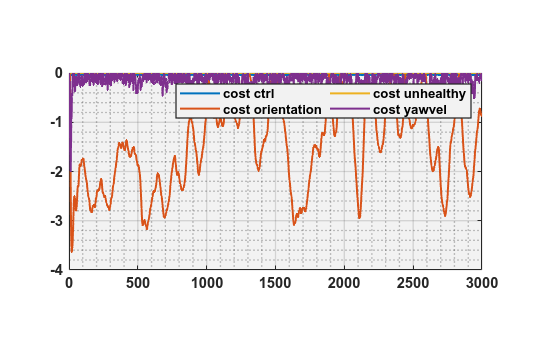


h=figure('Units', 'centimeters', 'Position', [5, 5, 15, 10]);
ax = gca; %let user change axis setting
ax.FontSize = 11; %axis fontsize 
ax.LineWidth = 1.0; ax.FontWeight="bold"; %axis linewidth and Fontweight
% ax.GridLineStyle = '--';
% ax.GridLineWidth = 1;
ax.GridColor='#202020';
% fontname(gcf,"Arial") 
ax.Color=[0.95 0.95 0.95];
box
pbaspect([2.1 1 1])

hold on;
%% 그래프 그리기
plot(x, cost_ctrl, 'LineWidth', 1.5, 'LineStyle', '-');
plot(x, cost_orientation, 'LineWidth', 1.5, 'LineStyle', '-');
plot(x, cost_unhealthy, 'LineWidth', 1.5, 'LineStyle', '-');
plot(x, cost_yaw_vel, 'LineWidth', 1.5, 'LineStyle', '-');

hold off;

legend('cost ctrl', 'cost orientation', 'cost unhealthy', 'cost yawvel', Location='northeast',NumColumns=2);

grid on;
box on;
grid minor;